# Exercise 3: Radar Performance Improvement

This example demonstrates how to use the Radar Designer app to perform system level analysis of a radar.  This app can be used to do link budget analysis for radar systems.

## Open the Radar Designer App

Use the 'RadarDesigner' command  to open the Radar Designer application.

radarDesigner

Load an existing Radar Designer session file into the Radar Designer app using the 'Open Session' button in the toolbar.

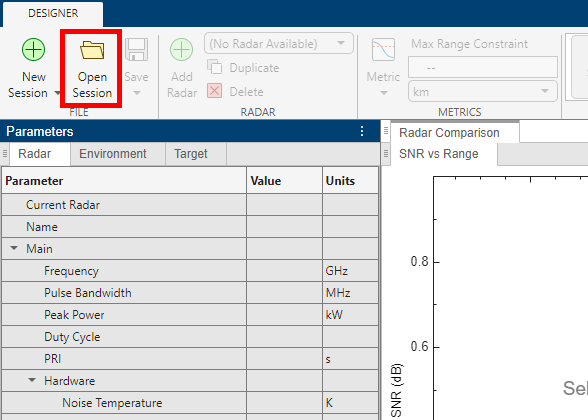

Select the file titled 'RadarWorkshopRadarDesignerFile.mat' and click 'Open' in the dialog that opens.

## Perform Analysis using the Radar Designer App

Examine the Radar Designer application.  There are a few things to point out in the app.

### Metrics

You are evaluating the probability of detection at a range of 40 km (the maximum range between the target and the radar in the scenario you are evaluating).

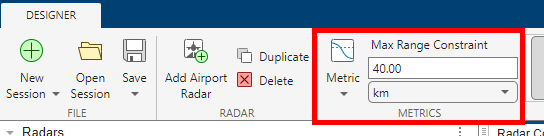

The evaluated probability of detection can be seen in the table in the bottom right of the app.  The objective probability of detection is 0.9 as it was in the script in exercise 2.  The threshold probability of detection is 0.75.  The threshold is the minimum required probability of detection and the objective is ideally how we would like the system to operate.  The probability of detection is evalutated at 40 km.  Currently, the probability of detection is ~0.32, which is well below the threshold, so the evaluated metric cell is red.  If the threshold for a metric is met but not the objective, the evaluated metric cell is yellow.  If the objective is met, the evaluated metric cell is greeen.

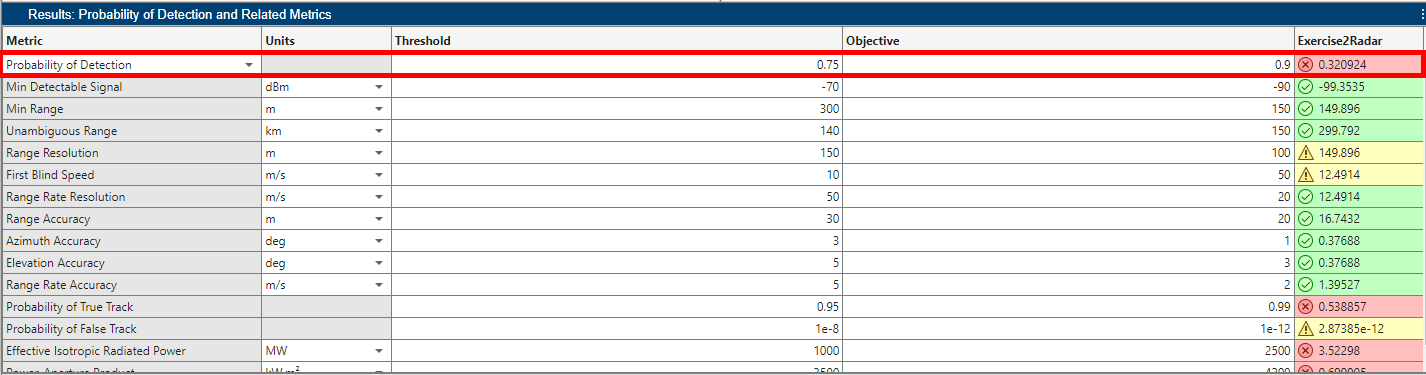

### Radar Parameters

The radar parameters from the script in exercise 2 have already been populated in this evaluation, but they don't meet your requirements.  All of the parameters can be seen in the panel on the left:

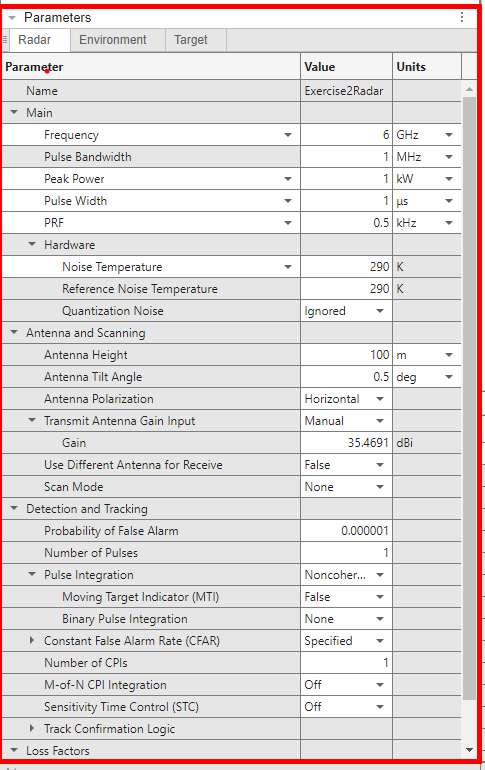

For this analysis, we want to be able to compare our modified radar performance to the radar's performance from exercise 2.  To this end, we will make a second radar so we can compare the two side by side.  To duplicate the radar, use the 'Duplicate' button in the 'Radar' section of the app toolbar:

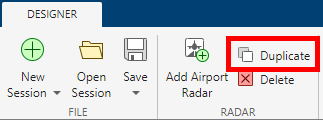

Rename the new radar to 'Exercise3Radar' or another name of your choice:

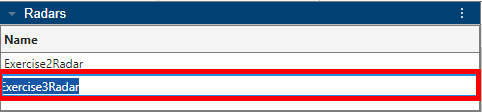

Two ways that we can potentially increase the probability of detection are by increasing the number of pulses integrated by the radar and by increasing the peak power.  Each of these options will have different pros and cons and may be useful in different situations.  Increasing the number of pulses to integrate will reduce the SNR required for a certain probability of detection.  Increasing the peak power of the radar system will increase the SNR received from a single individual pulse.

Once you are done making your modifications, select the radar you want to test in the 'Radars' panel:

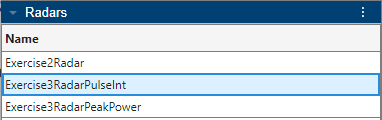

Now, export the analysis and radar design parameters using the 'Export' buttion.  Save the new script as 'newRadarDesign'.

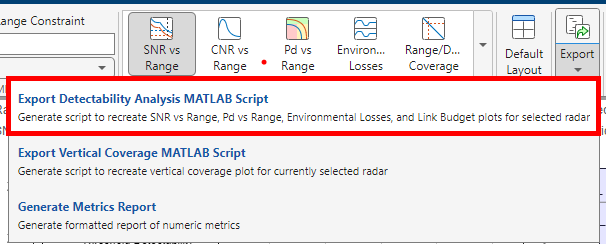

## New Radar Design Analysis

Next, let's re-run the analysis from the previous exercise with the newly designed radar.  Run this section of code with your exported file called 'newRadarDesign' to see how it performs!

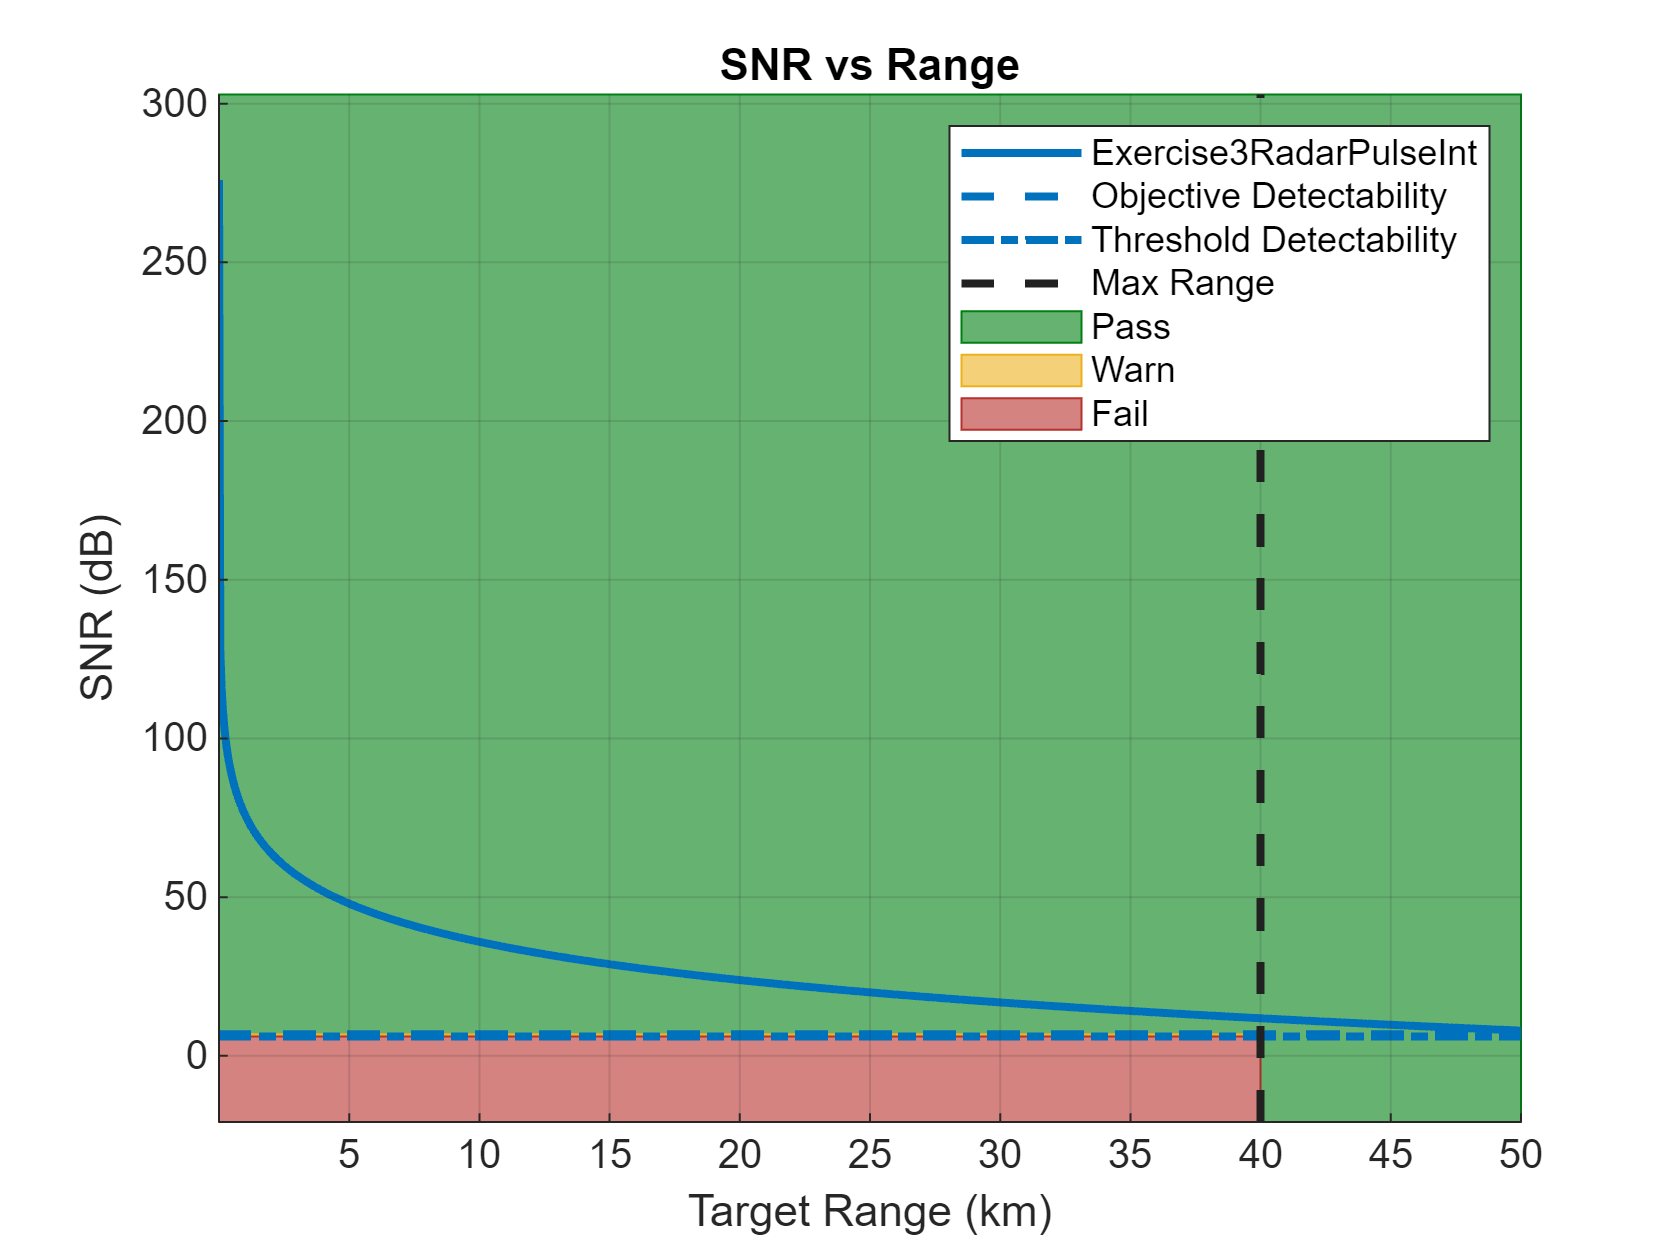

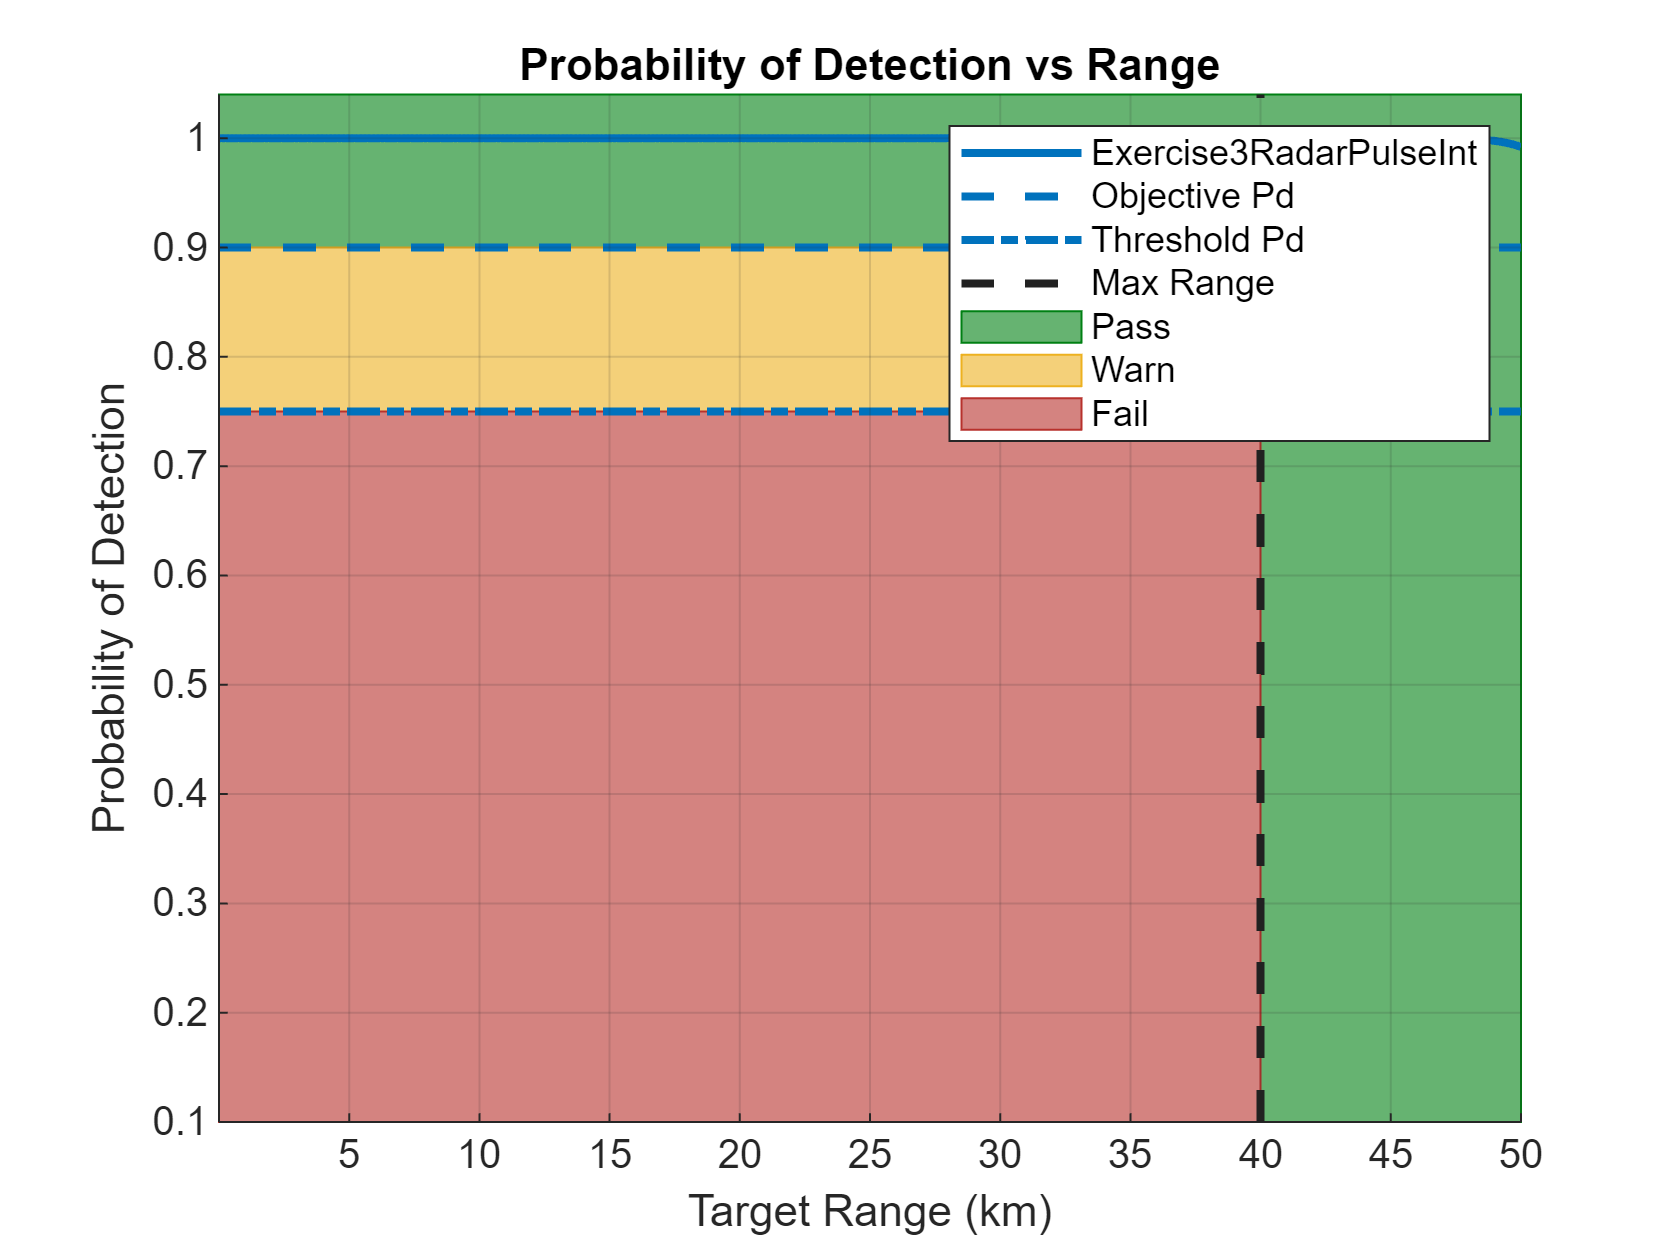

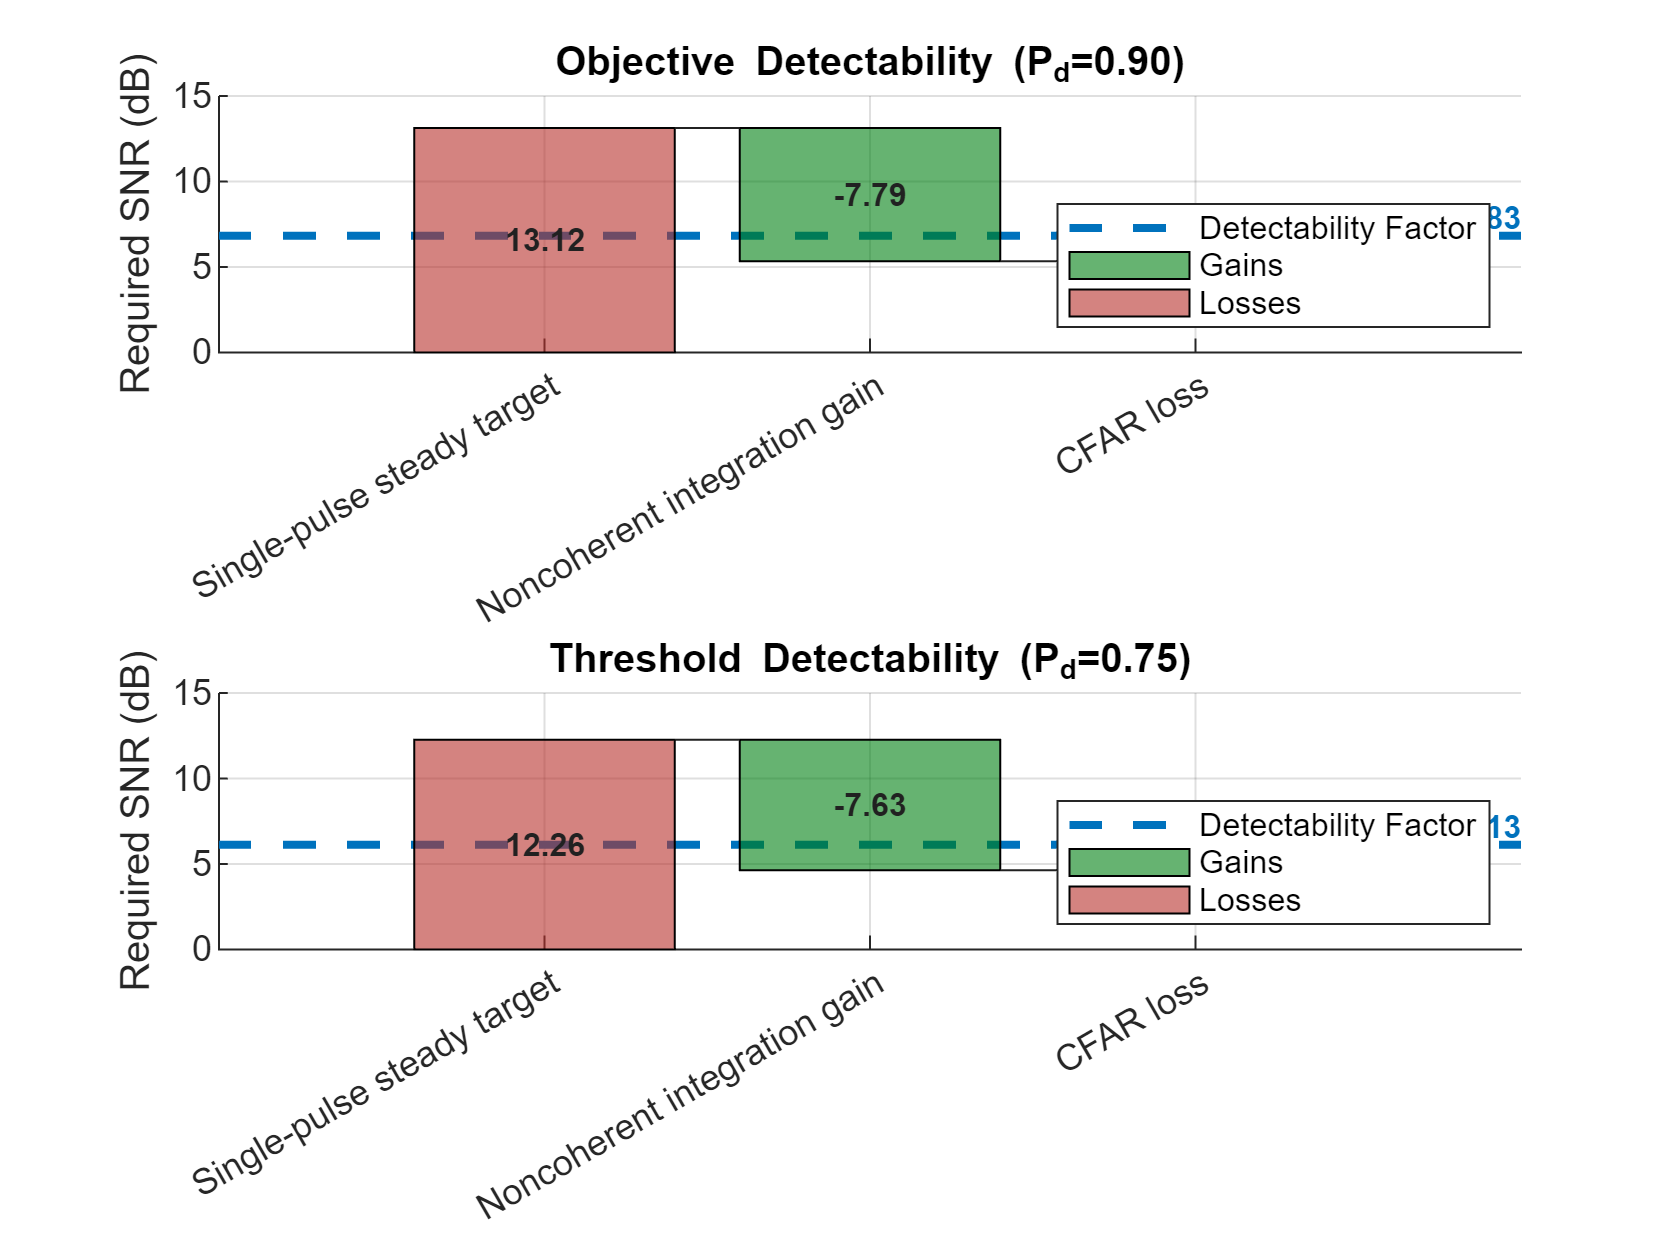

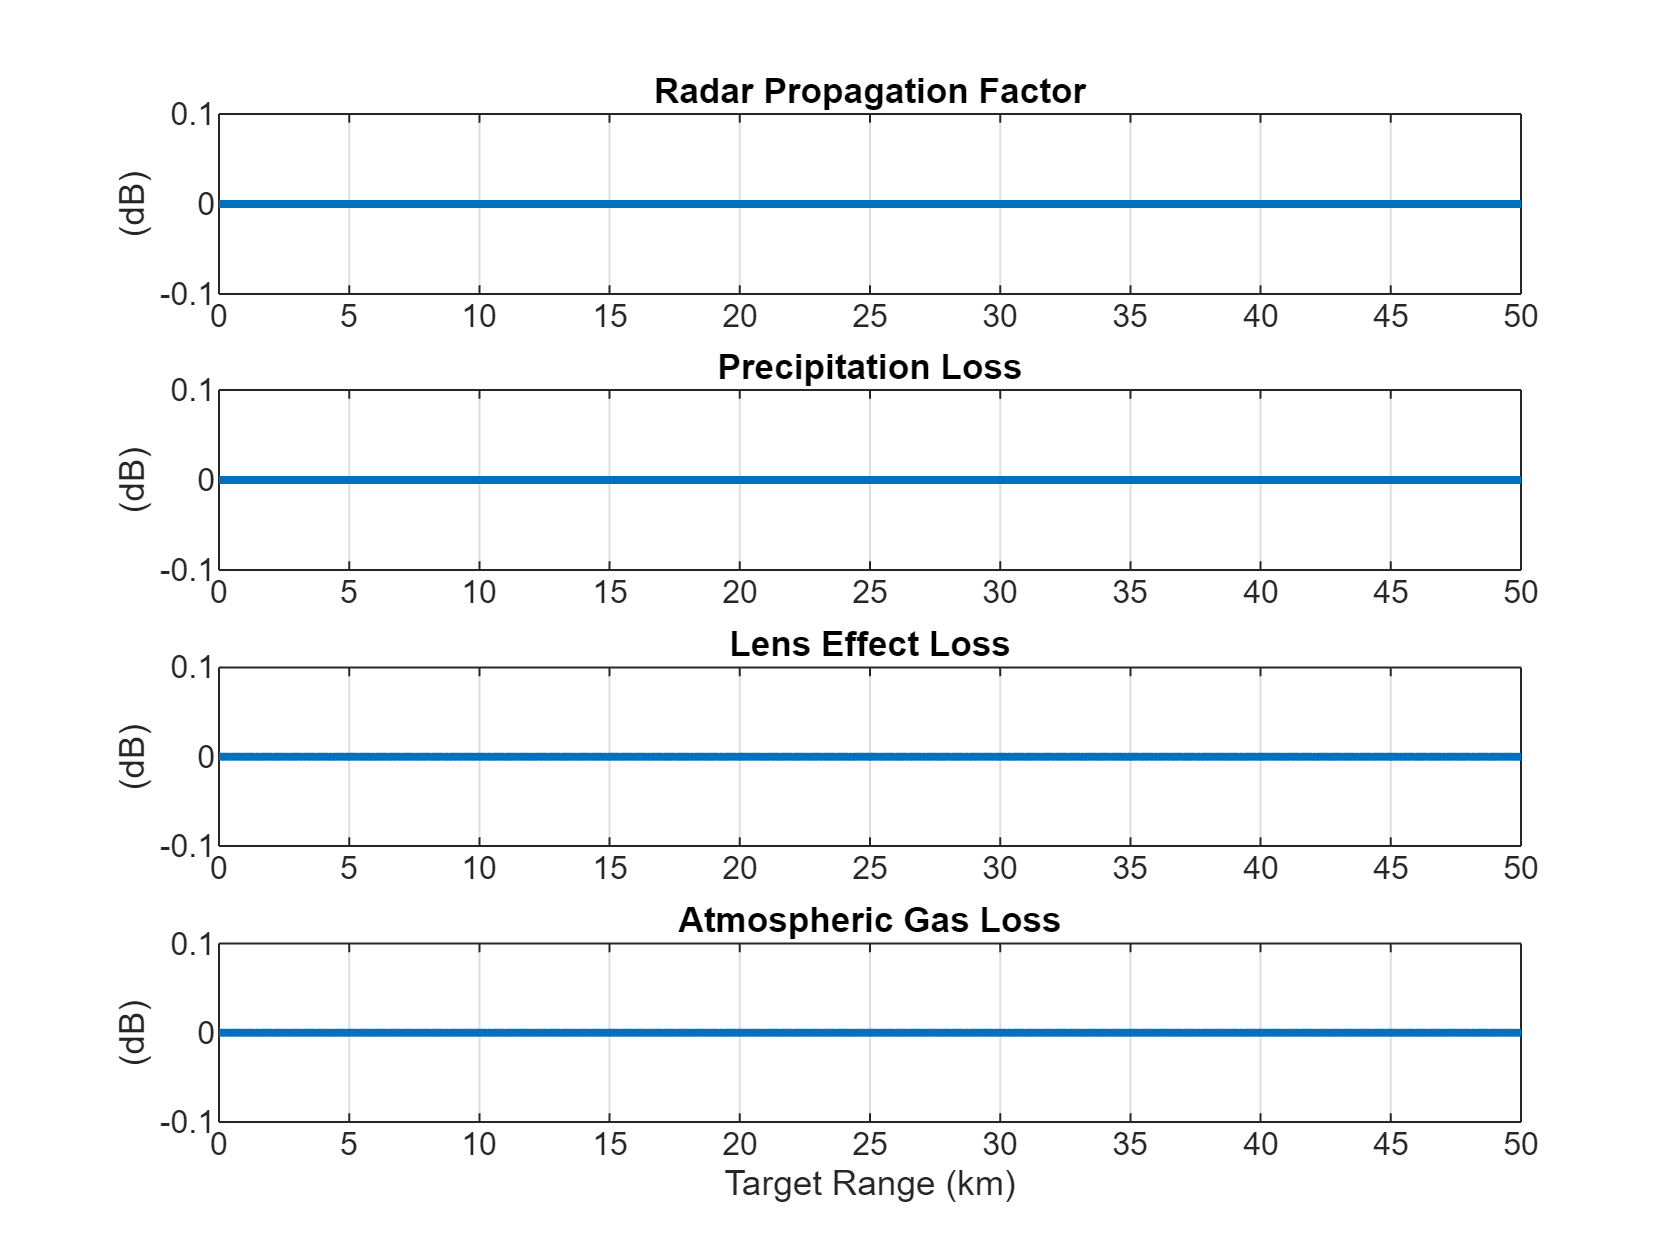

newRadarDesign;


updatedRadarAnalysis(radar.NumNonCoherentPulses, radar.PeakPower)

newMinimumSNR = detectability(.9, 1e-6, radar.NumNonCoherentPulses);

disp(newMinimumSNR)

    5.3336



## Conclusion

Now the target can be detected at every point along the trajectory where the target is not occluded from the radar by the mountains.

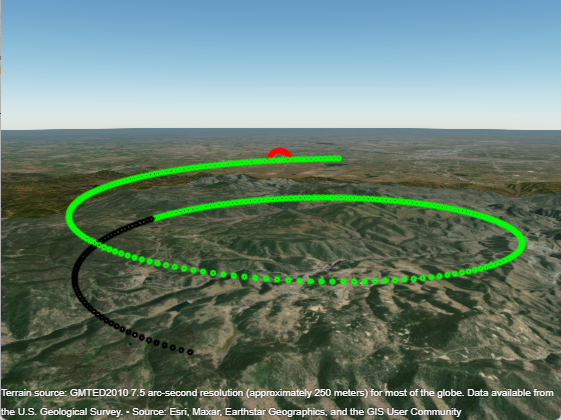

## Helper Functions

function updatedRadarAnalysis(numPulses, peakPower)
    frequency = 6e9; % Hz
    lambda = freq2wavelen(frequency); % signal wavelength in meters
    pt = peakPower; % peak radar power in Watts
    tau = 1e-6; % radar pulse width in seconds
    rcs = 10; % target radar cross section is ~10 m^2.  This is a name/value pair argument (use RCS=rcs syntax)
    
    hpbw = [2; 5]; % [az;el] degrees (clarify single sided vs. double sided)
    gain = beamwidth2gain(hpbw, 'CosineRectangular'); % gain in dBi.  This is a name/value pair argument (use Gain=gain syntax)
    
    fig = uifigure;
    g = geoglobe(fig);
    hold(g,"on")

    campos(g,39.77114,-105.62662,6670)
    camheading(g,70)
    campitch(g,-12)

    isEarthCentered = true; % This is a name/value argument (use the IsEarthCentered=isEarthCentered syntax)
    updateRate = 0.1; % Update rate for the scenario in Hz.  This is a name/value argument (use the UpdateRate=updateRate syntax)
    time=(0:299)/updateRate; % Simulation time steps in seconds.
    stopTime = time(end); % Stop time in seconds.  This is a name/value argument (use the StopTime=stopTime syntax)
    
    scene = radarScenario(IsEarthCentered=isEarthCentered,UpdateRate=updateRate,StopTime=stopTime);

    dtedfile = "n39_w106_3arc_v2.dt1";
    refl = surfaceReflectivityLand(Model = 'ConstantGamma', Gamma = -20);
    
    srf = landSurface(scene, Terrain=dtedfile, RadarReflectivity=refl); % SOLUTION

    rdrlat = 39.913756;         % Radar latitude (deg)
    rdrlon = -105.118062;       % Radar longitude (deg)
    rdrtowerht = 100;           % Antenna height (m)
    rdralt = 1717 + rdrtowerht; % Radar altitude (m)
    
    % Plot the radar location in the map
    h_rdrtraj = geoplot3(g,rdrlat,rdrlon,rdralt,"ro",LineWidth=6,MarkerSize=10);
    
    rdrplatform = platform(scene, Position=[rdrlat,rdrlon,rdralt]);

    [ttraj, tlat, tlon, talt] = DefineTarget(time, updateRate);

    trcs = pow2db(rcs);          % Target RCS (dBsm)

    tplatform = platform(scene,Trajectory=ttraj, ...
        Signatures={rcsSignature(Azimuth=[-180 180],Elevation=[-90 90],Pattern=trcs)});

    restart(scene)

    % Initialize a variable to keep track of the ranges between targets
    % throughout the scenario simulation
    trange = zeros(length(time), 1);
    
    % Initialize a variable to keep track of target visibility behind terrain
    % throughout the scenario simulation
    isVisible = false(size(time));
    
    % Keep track of the index of each of the above variables we are assigning
    % to throughout the duration of the simulation
    idx = 1;
    
    % Run the radar scenario using a while loop and the 'advance' function of
    % the radarScenario object
    while advance(scene)
        % Get the positions of each of the platforms (the radar and the target)
        % in geodetic coordinates at this time step
        tpose = pose(tplatform,CoordinateSystem="Geodetic");
        tpos = tpose.Position;
        rpose = pose(rdrplatform,CoordinateSystem="Geodetic");
        rpos = rpose.Position;
        
        % Determine whether the target is occluded from the radar by the
        % terrain model in the scenario.  This function returns 'true' if the
        % target is occluded and false if it is visible.
        isVisible(idx) = ~boolean(occlusion(scene.SurfaceManager, rpos, tpos));
    
        % Calculate the range between the radar and the target in meters based
        % on the radar and target geodetic coordinates
        trange(idx) = llarangeangle(rpos,tpos, 1);
    
        % Update the index for variable assignment
        idx = idx+1;
    end
    
    tsnr = radareqsnr(lambda,trange,pt,tau,RCS=rcs,Gain=gain);
    
    tsnr(~isVisible) = -inf;

    pd = 0.9;
    pfa = 1e-6;
    
    minimumSNR = detectability(pd,pfa, numPulses);

    PlotDetectable(minimumSNR, tsnr, g, isVisible, tlat, tlon, talt);
end

Consider a large commercial aircraft as the target. Assume the aircraft trajectory is a corkscrew maneuver, where the aircraft descends rapidly in a spiral.

function [ttraj, tlat,tlon, talt] = DefineTarget(time, updateRate)
    tlat0 = 39.80384;           % Target initial latitude (deg)
    tlon0 = -105.49916;         % Target initial longitude (deg)
    tht0 = 3000;                % Target initial height (m)
    azs = linspace(1, 540, numel(time));              % Target azimuth (deg)
    r = 5000;                   % Target slant range (m)
    
    % Convert from polar coordinates to Cartesian East, North, Up (ENU).
    [X,Y] = pol2cart(deg2rad(azs),r);
    
    % Convert ENU to geodetic.
    Z = linspace(2000, 0, numel(azs));
    wgs84 = wgs84Ellipsoid;
    [tlat,tlon,tht] = enu2geodetic(X,Y,Z,tlat0,tlon0,tht0,wgs84);
    
    % Define the target altitude.
    talt = tht - egm96geoid(tlat,tlon); % Target altitude (m)

For simplicity, assume the waypoints are obtained at a constant sampling rate of 0.1 Hz. The trajectory can be generated using `geoTrajectory` with positions specified as latitude, longitude, and altitude.

    ttraj = geoTrajectory([tlat.' tlon.' talt.'],time,SampleRate=updateRate);
end

Plot the detectability of the aircraft along its trajectory.

function detectablePlot = PlotDetectable(minimumSNR, tsnr, g, isVisible, tlat, tlon, talt)
    detectableColor = 'g';
    undetectableColor = 'r';
    color = repmat(undetectableColor, 1, length(isVisible));
    color(isVisible & (tsnr>minimumSNR)) = detectableColor;
    color(~isVisible) = 'k';

    detectablePlot = zeros(size(isVisible));

    for ii = 1:length(isVisible)
        detectablePlot(ii) = geoplot3(g, tlat(ii), tlon(ii), talt(ii), Marker='o', LineWidth=2, MarkerSize=1,...
            Color=color(ii));
    end
    
end